Reading the data from the source and converting the data into array

data=readtable("male_female.xlsx")

data = 30×3 table
    year    male    female
    ____    ____    ______

    2008     0.1        1 
    2009     0.2      0.3 
    2010     0.3     -0.4 
    2011     0.4     -1.1 
    2012     0.5     -1.8 
    2013     0.6     -2.5 
    2014     0.7     -3.2 
    2015     0.8     -3.9 
    2016     0.6     -2.5 
    2017     0.7     -3.2 
    2018     0.8     -3.9 
    2019     0.6     -2.5 
    2020     0.7     -3.2 
    2021     0.8     -3.9 
    2022    0.75    -3.55 
    2023    0.76    -3.62 



data=table2array(data)

data = 1.0e+03 *

    2.0080    0.0001    0.0010
    2.0090    0.0002    0.0003
    2.0100    0.0003   -0.0004
    2.0110    0.0004   -0.0011
    2.0120    0.0005   -0.0018
    2.0130    0.0006   -0.0025
    2.0140    0.0007   -0.0032
    2.0150    0.0008   -0.0039
    2.0160    0.0006   -0.0025
    2.0170    0.0007   -0.0032


Plot the graph for the women in the curve 

women=data(:,3)

women =     1.0000
    0.3000
   -0.4000
   -1.1000
   -1.8000
   -2.5000
   -3.2000
   -3.9000
   -2.5000
   -3.2000


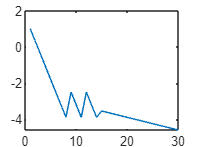


figure
plot(women)

year on the x axis

years=data(:,1)

years =         2008
        2009
        2010
        2011
        2012
        2013
        2014
        2015
        2016
        2017


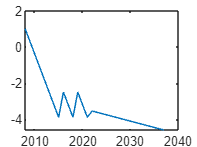

figure
plot(years,women)

men on the plot

men=data(:,2)

men =     0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.6000
    0.7000


figure
hold on
plotW=plot(years,women)

plotW =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2008 2009 2010 2011 2012 2013 2014 2015 2016 2017 2018 2019 2020 2021 2022 2023 2024 2025 2026 2027 2028 2029 2030 2031 2032 2033 2034 2035 2036 2037]
              YData: [1 0.3000 -0.4000 -1.1000 -1.8000 -2.5000 -3.2000 -3.9000 -2.5000 -3.2000 -3.9000 -2.5000 -3.2000 -3.9000 -3.5500 -3.6200 -3.6900 -3.7600 -3.8300 -3.9000 -3.9700 -4.0400 -4.1100 -4.1800 -4.2500 -4.3200 -4.3900 -4.4600 -4.5300 -4.6000]

  Show all properties


plotM=plot(years,men)

plotM =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2008 2009 2010 2011 2012 2013 2014 2015 2016 2017 2018 2019 2020 2021 2022 2023 2024 2025 2026 2027 2028 2029 2030 2031 2032 2033 2034 2035 2036 2037]
              YData: [0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.6000 0.7000 0.8000 0.6000 0.7000 0.8000 0.7500 0.7600 0.7700 0.7800 0.7900 0.8000 0.8100 0.8200 0.8300 0.8400 0.8500 0.8600 0.8700 0.8800 0.8900 0.9000]

  Show all properties


enhancing the  beauty of the plot

title('Unemployment rate of Nepal for both MEn ')
xlabel("number of years in the x axis")
ylabel("number of men and women rate in %")
legendme=legend('men','women')

legendme =   Legend (men, women) with properties:

         String: {'men'  'women'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7270 0.8210 0.1596 0.0793]
          Units: 'normalized'

  Show all properties


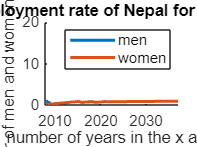

xlim([2008,2037])
ylim([0,20])
set(gca,'fontsize',10)
set([plotM,plotW],'linewidth',2)
set(legendme,'fontsize',10)